# Generate the kinematics for the Three-link 2D Biped

This function calculates the kinematics of the 3-link 2D biped. In particular, the position and velocities of the masses in an intertial frame. 

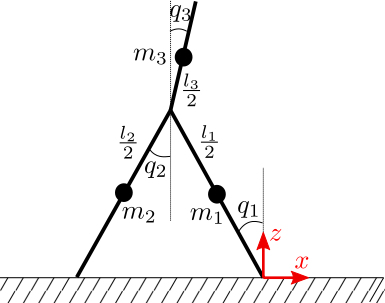

## The positions and velocities of the three masses $m_1$, $m_2$ , $m_3$:

syms x1 z1 x2 z2 x3 z3;
syms dx1 dz1 dx2 dz2 dx3 dz3;
syms q1 q2 q3;
syms dq1 dq2 dq3;
syms l1 l2 l3 

% write the symbolic formulas for x, z of masses m1, m2, m3:
x1 = l1/2*sin(q1);
z1 = l1/2*cos(q1);
x2 = 2*x1-l2/2*sin(q2);
z2 = 2*z1-l2/2*cos(q2);
x3 = 2*x1+l3/2*sin(q3);
z3 = 2*z1+l3/2*cos(q3);

% velocities of masses m1, m2, m3
dx1 = diff(x1,q1)*dq1+diff(x1,q2)*dq2+diff(x1,q3)*dq3;
dz1 = diff(z1,q1)*dq1+diff(z1,q2)*dq2+diff(z1,q3)*dq3;
dx2 = diff(x2,q1)*dq1+diff(x2,q2)*dq2+diff(x2,q3)*dq3;
dz2 = diff(z2,q1)*dq1+diff(z2,q2)*dq2+diff(z2,q3)*dq3;
dx3 = diff(x3,q1)*dq1+diff(x3,q2)*dq2+diff(x3,q3)*dq3;
dz3 = diff(z3,q1)*dq1+diff(z3,q2)*dq2+diff(z3,q3)*dq3;



## Positions and masses of other points of interest:

For the sake of visualization and later for control (e.g., foot-placement) we calculate the kinematics for some other points of interest as shown below:

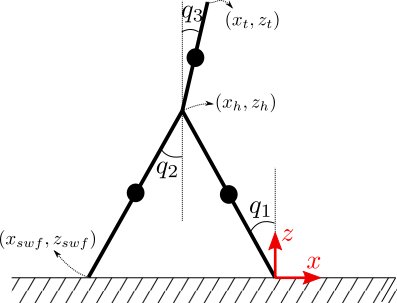

Variables definitions:

x_swf : Swing foot $x$-position

z_swf : Swing foot $y$-position

x_h : Hip $x$-position

z_h : Hip $y$-position

x_t : Torso top $x$-position

z_t : Torso top $y$-position

% Write the symbolic formulas for the hip, swing foot and torso end point
x_h = 2*x1;
z_h = 2*z1;

x_swf = x_h-l2*sin(q2);
z_swf = z_h-l2*cos(q2);

x_t = x_h+l3*sin(q3);
z_t = z_h+l3*cos(q3);

% velocities of masses x_h, z_h, x_swf, z_swf
dx_h = diff(x_h,q1)*dq1+diff(x_h,q2)*dq2+diff(x_h,q3)*dq3;
dz_h = diff(z_h,q1)*dq1+diff(z_h,q2)*dq2+diff(z_h,q3)*dq3;
dx_swf = diff(x_swf,q1)*dq1+diff(x_swf,q2)*dq2+diff(x_swf,q3)*dq3;
dz_swf = diff(z_swf,q1)*dq1+diff(z_swf,q2)*dq2+diff(z_swf,q3)*dq3;

## Convert symbolic equations to MATLAB functions:

To convert your symbolic equations to MATLAB functions you can print out the symbolic formulas into a file (e.g., tmp.txt). Open tmp.txt and copy-paste the formulas to your MATLAB function (e.g. you may want to use these formulas in the visualize.m function).

tmp = fopen('tmp.txt', 'wt');
fprintf(tmp, '%s = %s;\n', 'x1', char(x1));
fprintf(tmp, '%s = %s;\n', 'z1', char(z1));
fprintf(tmp, '%s = %s;\n', 'x2', char(x2));
fprintf(tmp, '%s = %s;\n', 'z2', char(z2));
fprintf(tmp, '%s = %s;\n', 'x3', char(x3));
fprintf(tmp, '%s = %s;\n', 'z3', char(z3));
fprintf(tmp, '%s = %s;\n', 'x_h', char(x_h));
fprintf(tmp, '%s = %s;\n', 'z_h', char(z_h));
fprintf(tmp, '%s = %s;\n', 'x_t', char(x_t));
fprintf(tmp, '%s = %s;\n', 'z_t', char(z_t));
fprintf(tmp, '%s = %s;\n', 'x_swf', char(x_swf));
fprintf(tmp, '%s = %s;\n', 'z_swf', char(z_swf));
fclose(tmp);